# Numerical Methods Assignment 2

Group 11

Noah Labuschagne S6621635

Danail Valov S5609895

Bashar Alsayed S4029291

**Instructions:**

- Submit the assignment by the deadline on Friday October 2 at 16:00 via Brightspace. All group members must be enrolled in the group before the assignment is submitted.

- **Submit two files: this .mlx file and an .pdf export of the same file. Save both files as NM_AS2_GroupX.mlx and NM_AS2_GroupX.pdf, replacing the X by your group number.**

- Ensure your group number, names and student numbers are at the top of the document.

- **Consult the course description for details** on the assignment, including information on the discussion and the generative AI policy.

- Include a statement on the ways in which you used generative AI, if any, in the box below. If you worked individually, ensure every group members writes their own statement.

- This type of MATLAB file is called a Live Code File Format (.mlx). It allows you to have all code in one place, and show code, generated figures, text, and equations all next to eachother. It is fairly self-explanatory, but this page and links within it provide some further explanation: [http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.](http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.) You are welcome to remove the text of the assignment or keep it and add in your solutions. 

## Generative AI statement

Noah Labuschagne: AI was not used to generate any code. AI was used infrequently for debugging.

## Set-up (15 pts.)

The main functions you will use in this assignment are the following. Define the functions here and ensure you call them when solving the problems.

% Implementation of the Jacobi method
function [x_k, xvec] = jacobi_iteration(A, x, b, maxit)

L = tril(A, -1);
D = diag(diag(A));
U = triu(A, 1);
it = 1;

xvec = zeros(length(x), maxit+1);

while it <= maxit
    xvec(:, it) = x;
    x_k = inv(D) * (b -(L+U) * x);

alphas =     0.0259
   -0.0036
    0.0016


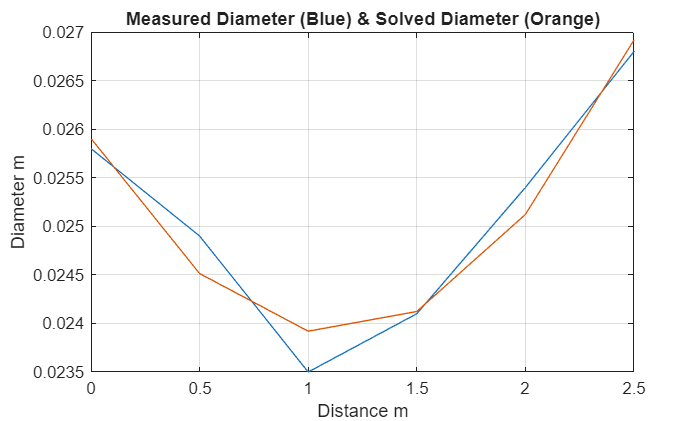

    x = x_k;
    it = it + 1;
end

% plotting
xvec(:, it) = x_k;
dexact = xvec(:, end);
itvec = 0:(size(xvec, 2)-1);
errvec = vecnorm(xvec - dexact, 2, 1) / vecnorm(dexact, 2);


figure, hold off
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on
end

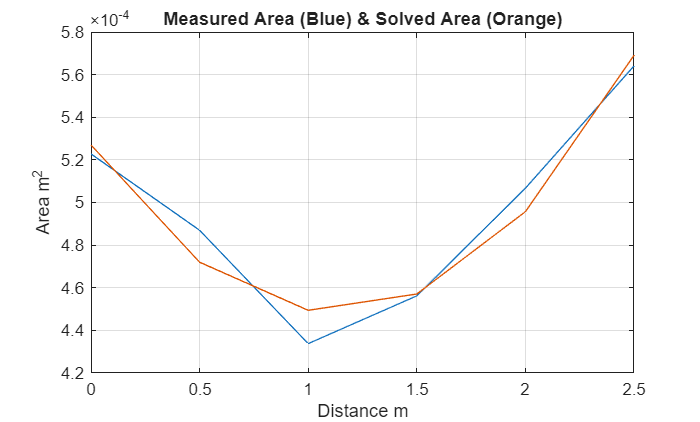

% Implementation of the Gauss-Seidel method
function [xk, xvec] = gauss_seidel(A, x, b, maxit)
it = 1;
len = length(b);

xvec = zeros(len, maxit+1);
xvec(:, it) = x;


while it <= maxit

    for i = 1:len
        sum = 0;
        for j = 1:len
            if j ~= i
                sum = sum + A(i,j) * x(j,1);
            end
        end

diameter_x_bar =     0.0253
    0.0243
    0.0239
    0.0243
    0.0257


        x(i,1) = (b(i,1) - sum) / A(i,i);

element_area_calculated = 1.0e-03 *

    0.5008
    0.4619
    0.4485
    0.4637
    0.5206


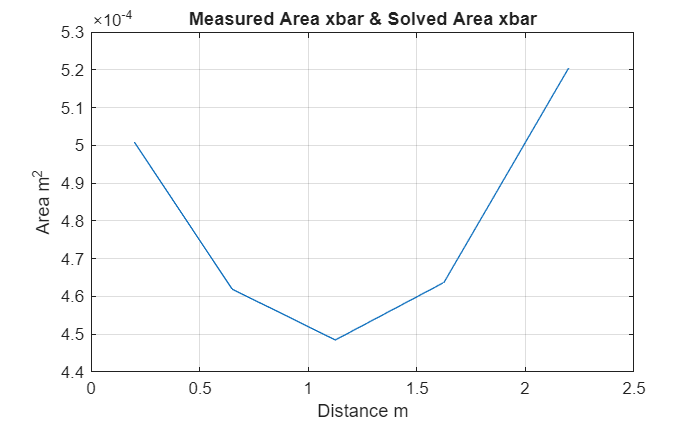

    end

    it = it + 1;
    xvec(:, it) = x;
end
xk = x;


% plotting
dexact = xvec(:, end);

itvec = 0:(size(xvec, 2)-1);
errvec = vecnorm(xvec - dexact, 2, 1) / vecnorm(dexact, 2);

figure, hold off
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on
end

% Implementation of the composite midpoint rule
function [I] = composite_midpoint(f, a, b, n)
vec = zeros(1, n);
total_interval = b-a;
interval = total_interval/n;


for k = 1:n
    area_interval = interval * f((a+(k-1)*interval + a+k*interval)/2);
    vec(k) = area_interval;
end

I = sum(vec);
end

K = 778.5071

% Implementation of the composite trapezoidal rule

n = 0.1896

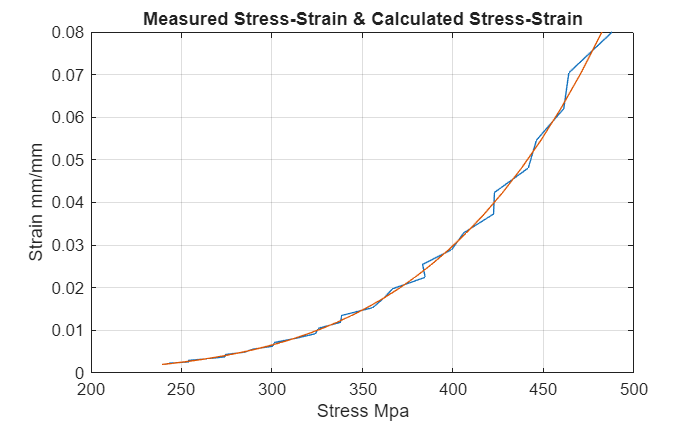

function [I] = trapezoid(f, a, b, n)
vec = zeros(1, n);
total_interval = b-a;
interval = total_interval/n;

for k = 1:n
    area_interval = ((f(a + (k-1)*interval) + f(a + k*interval))/2) * interval;
    vec(k) = area_interval;
end


I = sum(vec);
end

% Implementation of the composite Simpson's 1/3 rule
function [I] = simpson(f, a, b, n)

Eeq = 6.1646e+03

vec = zeros(1, n);
total_interval = b-a;
interval = total_interval/n;

for k = 1:n
    a0 = a + (k-1)*interval;
    b0 = a + k*interval;

stiffness =     5.1456
    4.7461
    4.6078
    4.7642
    5.3484


    area_interval = (interval/6) * (f(a0) + 4*f((a0+b0)/2) + f(b0));
    vec(k) = area_interval;
end
I = sum(vec);
end

## Problem 1: Numerical Methods for a loaded Bar (45 pts) 

A single straight bar has a cross-section that varies continuously along its axis according to a quadratic approximation. For the numerical analysis, the same bar is discretized into five axial elements joined at six nodes; these elements are not separate bars or physical steps. The left and right ends are fixed, and four concentrated axial forces are applied at the internal nodes. Positive force and positive displacement point to the right.

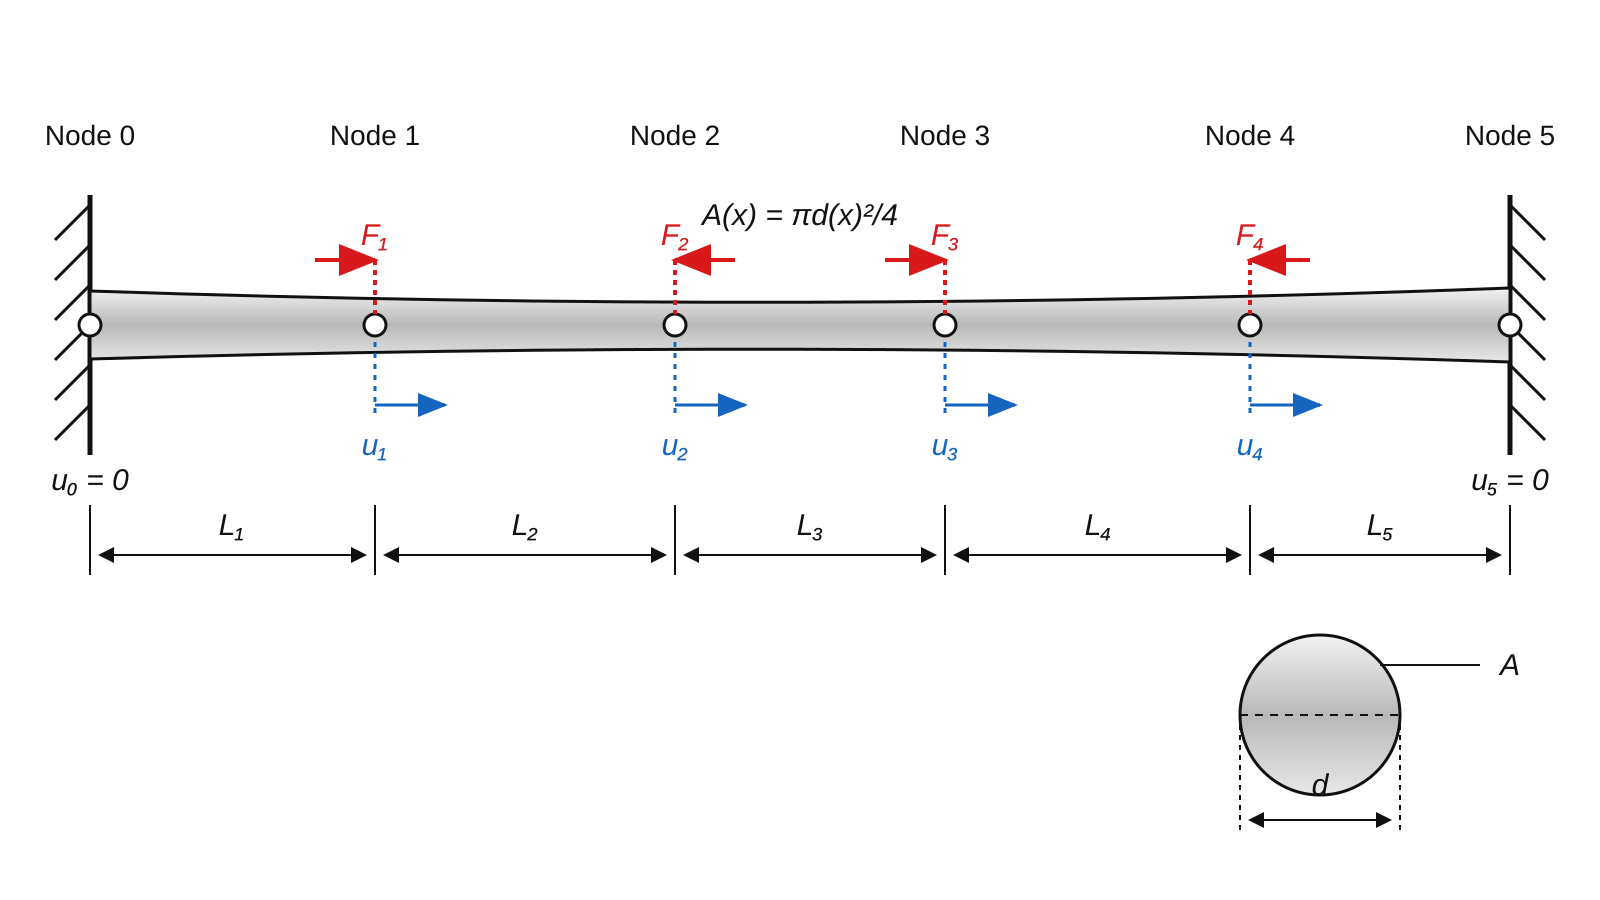

The goal of this problem is to determine the internal displacements $u_1, u_2,u_3,u_4$.

**Equilibrium analysis to determine internal displacements**

We call the segment between node $e-1$ and $e$ element $e$. That is, the segment between node 0 and 1 is element 1. The internal axial force $N_e$ in element $e$ is 


$$N_e = k_e(u_e-u_{e-1}),$$


where $k_e$ is the equivalent axial stiffness. A positive $N_e$ means the segment is stretched (in tension) and a negative $N_e$ means it is compressed. You can interpret this formula as Hooke's law written in terms of the two nodal displacements that bound the element — exactly like a spring of stiffness $k_e$ connecting node $e-1$to node $e$.

For a single node $i$, sitting between element $i$ on its left and $i+1$ on its right. Physically, a stretched segment pulls its two end‑nodes towards each other:

- Element $i$, if in tension, pulls node $i$ backward (toward node $i-1$) with magnitude $N_i$.

- Element $i+1$, if in tension, pulls node $i$ forward (toward node $i+1$) with magnitude $N_{i+1}$�.

Since all nodes are in a static equilibrium, the externally applied force $F_i$ must balance the net pull from the two segments:

$F_i = N_i-N_{i+1}$�

These equations allow you to determine the displacements.

**Plan**

Some of the data you need to determine the displacements is provided, other data you will have to determine empirically using measured data from the workbook *`stepped_bar_measurements.xlsx`.*

We will undertake the following steps

a. **Geometry characterization:** Determining the bar's geometry based on measurements taken at various positions along its axis.

b. **Material characterization:** Determining characteristic parameters of the material using measured stress–strain data.

c. **Structural analysis:** Calculating segment stiffness, segment forces and segment stresses.

d. **Volume determination: **computing the total volume of the bar. 

#### Structural data

The node positions are


$$
 \mathbf x=[0.00,\ 0.40,\ 0.90,\ 1.35,\ 1.90,\ 2.50]\ \mathrm{m}.
$$


The main forces applied at nodes 1 through 4 are


$$
 \mathbf F=[35,\ -20,\ 45,\ -25]^T\ \mathrm{kN}.
$$


#### Symbols

### Problem 1a. Geometry characterization (7 pts)

i) The bar diameter is represented by the single continuous polynomial $d(x)=a_0+a_1x+a_2x^2$. Determine the least squares fit to the data presented in the *`diameter_measurements' *worksheet of the workbook *`stepped_bar_measurements.xlsx`*. Plot the datapoints and fitted curve.

ii) Use the empirical bar diameter to calculate the circular cross-section area. Plot the area

$A(x)=\frac{\pi}{4}[d(x)]^2$.

Convert $d(x)$ from $\mathrm{mm}$ to $\mathrm{m}$ before calculating area in $\textrm{m}^2$.

iii) For the discrete structural model, the area of element $e$ is evaluated at its midpoint $\bar{x}_e=(x_{e-1}+x_e)/2$:


$$A_e=A(\bar{x}_e)=\frac{\pi}{4}[d(\bar{x}_e)]^2.$$


Compute the area of each of the elements.

# Solution 1a

#### Data Loading

DM = readmatrix("stepped_bar_measurements.xlsx", 'Sheet', 'diameter_measurements');

F =     35
   -20
    45
   -25


Loading the Diameter measurements from the excel file stepped_bar_measurements.xlsx.

#### Solution 1a i)

x_vals = DM(:, 1); % Measured Distance
diameter_measured = DM(:, 2)./1000; % Measured Diameter in Meters

X = zeros(6, 3); % 6 by 3
X(:, 1) = 1;
X(:, 2) = x_vals;
X(:, 3) = x_vals.^2;

matrix_K =     9.8917   -4.7461         0         0
   -4.7461    9.3539   -4.6078         0
         0   -4.6078    9.3720   -4.7642
         0         0   -4.7642   10.1126


displacement_u =     5.6776
    4.4586
    7.5436
    1.0817


alphas = X\diameter_measured
diameter_calculated = alphas(1,1) + alphas(2,1).*x_vals + alphas(3,1).*(x_vals.^2); % Solving the Polynomial

% plotting
figure;

displacement_u =     5.6776
    4.4586
    7.5436
    1.0817


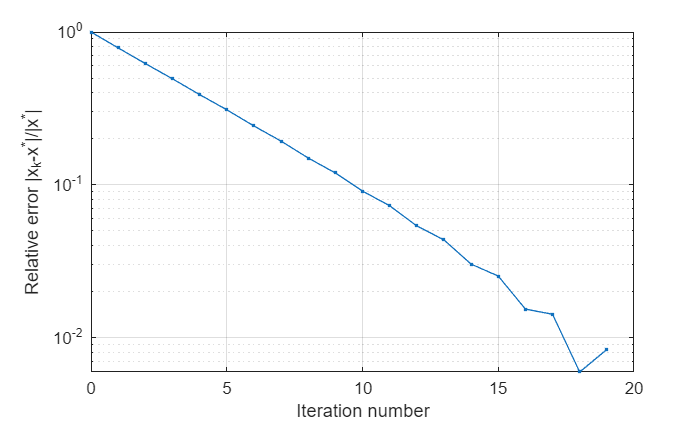

displacement_jacobi_iteration =     5.6271
    4.4200
    7.4604
    1.0589


plot(x_vals, diameter_measured, x_vals, diameter_calculated)
hold off;
xlabel('Distance m')
ylabel('Diameter m')
title('Measured Diameter (Blue) & Solved Diameter (Orange)')
grid on;

The measured diameters of the bar are divided by a thousand to obtain the values in meters before using the least squares method to solve for the approximate constants (alphas) of the linearized equation. The solved constants are then used to calculate the approximate diameter of the bar at each of the measured distances and are plotted against the measured values on a distance-diameter graph. The solved diameter produces a much smooter curve than the measured values.

#### Solution 1a ii)

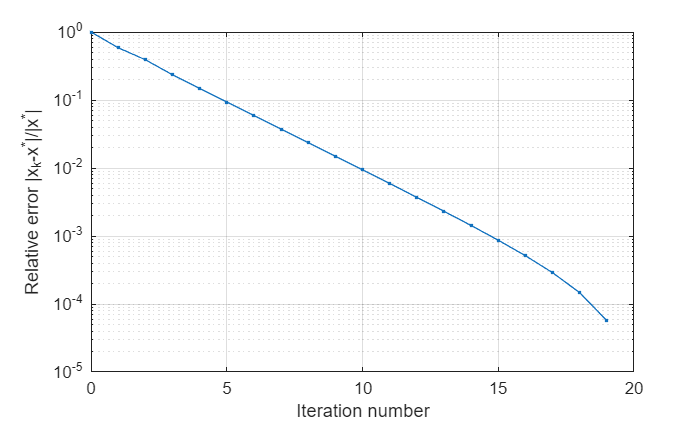

displacement_gauss_seidel =     5.6771
    4.4580
    7.5430
    1.0814


area_measured = (pi/4).*(diameter_measured.^2);
area_calculated = (pi/4).*(diameter_calculated.^2);

% plotting
figure;
plot(x_vals, area_measured, x_vals, area_calculated)

hold off;
xlabel('Distance m')
ylabel('Area m^2')
title('Measured Area (Blue) & Solved Area (Orange)')
grid on;

Both the measured and calculated diameter values (already in meters) are used to calculate the area of the bar at each of the 6 points (0, 0.5, 1, 1.5, 2, 2.5), and are plotted against each other, producing a graph which resembles the distance-diameter graph in terms of relative error with minor differences stemming from the exponent of the diameter in the equation.

#### Solution 1a iii)

node_x_vals = [0; 0.4; 0.9; 1.35; 1.9; 2.5];
x_bar = zeros(5,1);

for k = 1:5
    x_bar(k,1) = (node_x_vals(k,1) + node_x_vals(k+1,1))/2;
end


deflection_between_nodes =     5.6776
   -1.2190
    3.0849
   -6.4619
   -1.0817


diameter_x_bar = alphas(1,1) + alphas(2,1).*x_bar + alphas(3,1).*(x_bar.^2) % Solving the Polynomial

axial_strain =     9.4627
   -2.0316
    5.1415
  -10.7698
   -1.8028


element_area_calculated = (pi/4).*(diameter_x_bar.^2) % calculating the area


equivalent_linear_stress = 1.0e+04 *

    5.8334
   -1.2524
    3.1695
   -6.6391
   -1.1114


internal_axial_force_linear =    29.2147
   -5.7853
   14.2147
  -30.7853
   -5.7853


% plotting
figure;

fitted_nonlinear_stress = 1.0e+03 *

    1.1921
   -0.8905
    1.0619
   -1.2218
   -0.8706


plot(x_bar, element_area_calculated)

internal_axial_force_nonlinear =     0.5971
   -0.4114
    0.4763
   -0.5665
   -0.4532


hold off;
xlabel('Distance m')
ylabel('Area m^2')
title('Measured Area xbar & Solved Area xbar')
grid on;

Utilizing the midpoint between position xe-1 and xe to determine the diameter of each of the elements from the matrix [0; 0.4; 0.9; 1.35; 1.9; 2.5] based on the fitted polynomial, the area of each is calculated, before being plotted at the midpoint between each of the nodes.

### Problem 1b. Material characterization  (10 pts)

i) The relationship between axial strain and stress can be described by the nonlinear relationship

$  $$\sigma=K\varepsilon^n$$$,

where $K>0$ and $n$ are unknown. Determine estimates for the parameters $K$ and $n$ using a linear least squares fit. The data to fit to can be found in the *`power_law_test` *worksheet of the workbook *`stepped_bar_measurements.xlsx`*. Plot the datapoints and fitted curve.

ii) The fitted relationship is nonlinear, but the required structural system is linear. A tangent modulus is therefore evaluated at a selected reference strain:


$$E_{\mathrm{eq}}
 =\left.\frac{d\sigma}{d\varepsilon}\right|_{\varepsilon_{\mathrm{ref}}}
 =Kn\varepsilon_{\mathrm{ref}}^{n-1}$$


Use the reference strain


$$\varepsilon_{\mathrm{ref}}=0.010$$


Determine the equivalent tangent modulus based on your fit of the stress-strain relationship. Ensure consistent units are used.

iii) Finally, calculate the element stiffness for each element using the formula

$k_e=\frac{E_{\mathrm{eq}}A_e}{L_e}$.

# Solution 1b

#### Data Loading:

SS = readmatrix("stepped_bar_measurements.xlsx", 'Sheet', 'power_law_test');

f = function_handle with value:
    @(x)0.0259-0.00358*x+0.00159*x^2


stress = SS(:, 2);

l = 0

strain = SS(:, 1);

u = 2.5000

#### Solution 1b i)

% stress = K*strain^n
% log(stress) = log(K) + n * log(strain)

composite_midpoint_volume =     0.0598    0.0618    0.0618



X = ones(30, 2);

trapezoid_volume =     0.0660    0.0620    0.0619


X(:, 2) = log(strain);


simpson_volume =     0.0618    0.0618    0.0618


betas = X\log(stress);

K = exp(betas(1))
n = betas(2)
stress_calculated = K * strain.^n;

% plotting
figure;
plot(stress, strain, stress_calculated, strain)
hold off;
xlabel('Stress Mpa')
ylabel('Strain mm/mm')
title('Measured Stress-Strain & Calculated Stress-Strain')
grid on;

Firstly, the governing equation between the stress and the strain was linearized and the governing constants (K & n) were determined via the least squares method. Afterwards, the approximate stress values relative to the stress were determine with those constants and both the measured stress curve and the calculated fitted stress curve were plotted against each other at the given strain values. 

The calculated graph line is significantly smoother than the graph line of the measured values which is more jagged and has jumps at various points along its length.

#### Solution 1b ii)

Eeq = K*n*0.01^(n-1)

The tangent modulus at the reference strain 0.01 is approximately 6.1646 Gpa based on the derived constants (betas) of the fitted curve which governs the stress-strain relationship.

#### Solution 1b iii)

for i = 1:5
L_nodes = node_x_vals(i+1) - node_x_vals(i);
end

stiffness = (Eeq*element_area_calculated)./L_nodes

After storing the length of each of the elements, the element stiffness of each element is calculated relative to the calculated area and the calculated length of the nodes; however, it should be noted that the calculated stiffness values are inacurrate due to the application of the static reference strain value to calculate the tangent modulus of the beam; more accurate results would necesitate the calculation of the tangent modulus relative to the experienced strain instead of at an arbitrary reference strain value.

### Problem 1c. Structural analysis  (20 pts)

i) Use the equilibrium analysis to determine internal displacements at the top of the problem to determine four equations for our four unknown internal-node displacements. The equations should be in terms of the element stiffnesses and the applied forces. The resulting linear system of equations should be of the form


$$\mathbf K\mathbf u=\mathbf F$$


where $\mathbf{K}$ is a symmetric $4\times 4$ matrix with positive diagonal entries. 

ii) Solve the system with a direct solver, Jacobi, and Gauss-Seidel. Specify which direct method you used and why. Compare the convergence behaviour of either iterative method and compare the convergence behaviour with the theoretical rates of convergence. Which of the three methods (direct, Jacobi, Gauss-Seidel) would you prefer to solve this system?

iii) For each segment, calculate the axial strain using

$\varepsilon_e=\frac{\delta_e}{L_e}$, where $\delta_e=u_e-u_{e-1}$, 

Two stress evaluations must be clearly distinguished:

1. the stress consistent with the equivalent linear structural solve,


$$  $$\sigma_{e,\mathrm{eq}}=E_{\mathrm{eq}}\varepsilon_e$$$$


2. the stress predicted by the fitted nonlinear material relationship,

$$$\sigma_{e,\mathrm{nl}}=K\,{\mathrm{sgn}}(\varepsilon_e)|\varepsilon_e|^n$$$.

Then calculate the corresponding internal axial force consistently as


$$N_e=A_e\sigma_e
$$


iv) Finally, classify each element as tension when $$\varepsilon_e>0$$**, **compression when $$\varepsilon_e<0$$, or zero response when the strain is numerically zero.

# Solution 1c

#### Solution 1c i)

F = [35; -20; 45; -25]
matrix_K = [(stiffness(1) + stiffness(2)), -stiffness(2),       0,         0;

            -stiffness(2), (stiffness(2) + stiffness(3)), -stiffness(3),   0;


const1 = 2.1906e-08

            0,    -stiffness(3), (stiffness(3) + stiffness(4)), -stiffness(4);

const2 = 4.9738e+03


            0,      0,     -stiffness(4),      (stiffness(4) + stiffness(5))]

muT =     0.5118
    0.4434
    0.3851
    0.3352
    0.2924
    0.2557
    0.2241
    0.1968
    0.1732
    0.1527
    0.1349
    0.1194
    0.1059
    0.0941
    0.0838


displacement_u = matrix_K\F

ypts =     0.5146
    0.4414
    0.3860
    0.3326
    0.2937
    0.2550
    0.2257
    0.1957
    0.1732
    0.1535
    0.1343
    0.1197
    0.1052
    0.0944
    0.0837


Since the stiffness values are calculated at the midpoint between each of the nodes, the stiffness at each node along the diagonal of the matrix (the points where the forces are acting), depend on the sum of the stiffnesses of the elements on either side of that node. Since the forces acting on the neighboring nodes also displace the node in question, the negative stiffness of the adjacent element is located on the off diagonal of the matrix.

Solving the linear system of equations of K to obtain the force values F produces the displacement of each node stored in the matrix u.

#### Solution 1c ii)

% Direct Solving (Already conducted in 1c. i)
displacement_u = matrix_K\F

A = matrix_K;

max_relative_error = 0.0077

b = F;
x = [0;0;0;0];
maxit = 20;
displacement_jacobi_iteration = jacobi_iteration(A, x, b, maxit)

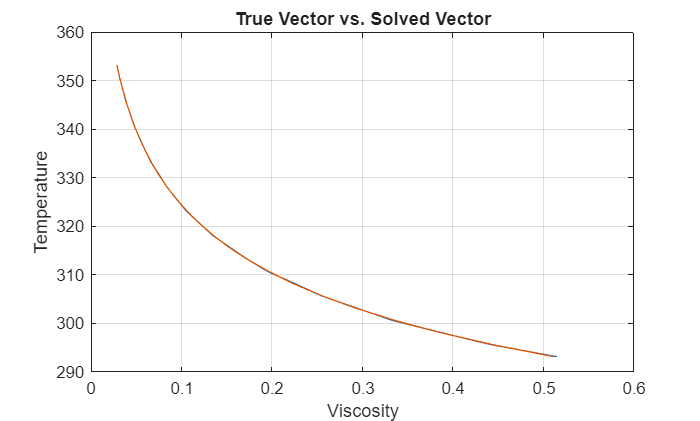

A = matrix_K;
b = F;
x = [0;0;0;0];
maxit = 20;


displacement_gauss_seidel = gauss_seidel(A, x, b, maxit)

The direct method utilized to solve this system of linear equations was the backslash operator which conducts an LU decomposition and directly solves for the analytical solution of the given matrices. This method was chosen as it has been optimized by Matlab and has a significantly lower computational cost than any programmed LU decomposition.

In this instance, the Gauss-Seidel method converges towards the analytical solution twice as fast as the Jacobi method, attaining the same fidelity in only half the iterations, and then continuing to approach the analytical solution over the remainder of its iterations attaining an approximation which is two orders of magnitude closer to the analytical solution than the Jacobi method in the maximum number of iterations. This is exactly in line with the theoretical rate of convergence for both of these methods; typically the Gauss-Seidel method converges to the analytical solution twice as fast as the Jacobi method.

Since the direct method converges to the correct analytical solution instantaneously, does not require multiple iterations, and is the easiest out of all three methods to implement, it is the preffered method to solve this system of linear equations (and all systems of linear equations).

#### Solution 1c iii)

deflection_between_nodes = zeros(5, 1);

deflection_between_nodes(1) = displacement_u(1) - 0;
deflection_between_nodes(2) = displacement_u(2) - displacement_u(1);
deflection_between_nodes(3) = displacement_u(3) - displacement_u(2);
deflection_between_nodes(4) = displacement_u(4) - displacement_u(3);
deflection_between_nodes(5) = 0 - displacement_u(4);

deflection_between_nodes
axial_strain = deflection_between_nodes./L_nodes

equivalent_linear_stress = Eeq*axial_strain
internal_axial_force_linear = element_area_calculated.*equivalent_linear_stress

fitted_nonlinear_stress = K .* sign(axial_strain) .* (abs(axial_strain)).^n
internal_axial_force_nonlinear = element_area_calculated .* fitted_nonlinear_stress

After determining the deflection between each of the nodes based on the displacement at each of the nodes, and subsequently determining the axial strain acting on each of the nodes, both the stress and the axial strain were calculated for both the equivalent linear model as well as the fitted nonlinear model. 

The results of both models differ tremendously, with much higher variation as well as much higher values being produced by the linear model in comparison to the nonlinear model; however, the predictions of both models as to whether the node in question is in tension or under compression are consistent with each other and with what is expected when looking at the directions and magnitudes of the forces in the presented figure at the beginning of problem 1.

#### Solution 1c iv)

The first element (between node 0 and node 1) is in tension, due to the large force acting away from node 0 at node 1, consistent with the positive values obtained for the deflection, strain stress, and the internal axial force.

The second element (between node 1 and node 2) is under compression since the forces at these nodes are acting towards one another, also consistent with the calculated negative values of the deflection, strain, stress, and a the internal axial force.

The third element (between node 2 and node 3) is under tension since the forces at these nodes are acting against one another, consistent with the positive calculated values.

The fourth element (between node 3 and node 4) is under compression, because the forces at the nodes in question are acting towards each other, which is consistent with the calculated positive values.

Finally, the fifth element (between node 4 and node 5) is also under compression; despite the fact that the force at node 4 is acting away from node 5, the cumulative forces acting on the beam towards node 5 are greater than the cumulative forces acting away from it, thereby compressing the element. This is also consistent with the positive calculated values for the deflection, strain, stress, and the internal axial force.

### Problem 1d. Volume determination (8 pts)

The total volume of the bar is

$V=\int_0^{2.5}A(x)\,dx$.

Use the empirical expression for the cross-sectional area from part 1a to compute the total volume of the bar. First, compute the integral analytically. Next, use the three Newton-Cotes rules discussed in class to approximate the integral. For each of the rules, analyse how quickly the errors decrease as the number of function evaluations is increased. Which of the rules do you prefer here?

# Solution 1d

The analytical linearized expression derived in 1 a) for the area is approximated by:


$$0.0259 - 0.00358x + 0.00159x^2$$


The analytical integral of this expression is:


$$0.0259x - 0.00179x^2 + 0.00053x^3$$


When evaluated from 0 to 2.5, this expression yields a total volume of:


$$0.0259x - 0.00179x^2 + 0.00053x^3]_0^{2.5}
= 0.061844 m^3$$


Now that the definite integral of the linearized approximation has been evaluated analytically, we can utilize each of the three integration techniques  n = 1, 5, & 25 in order to determine the necessary number of function evaluations for these solutions to converge with the analytical solution to the definite integral of the polynomial.

f = @(x) 0.0259 - 0.00358*x + 0.00159* x^2
l = 0
u = 2.5

composite_midpoint_volume = [composite_midpoint(f, l, u, 1), composite_midpoint(f, l, u, 5), composite_midpoint(f, l, u, 25)]

trapezoid_volume = [trapezoid(f, l, u, 1), trapezoid(f, l, u, 5), trapezoid(f, l, u, 25)]

simpson_volume = [simpson(f, l, u, 1), simpson(f, l, u, 5), simpson(f, l, u, 25)]

Both the composite midpoint method and the trapezoid method converge on the analytical solution in as few as 5 intervals (function evaluations), while the simpson 1/3 rule converges on the analyical solution within a single interval.

From an objective standpoint, since the simpson rule requires only a single function evaluation to converge with the analytical solution to this definite integral, the composite 1/3 simpson rule is the preffered method for deriving the approximate solution to the integral of the polynomial expression.

## Problem 2: Numerical Analysis of a Hydrodynamic Slider Bearing (30 pts)

## What is a hydrodynamic bearing?

A hydrodynamic bearing is a machine element in which two solid surfaces are completely separated by a thin film of lubricant. When one surface moves relative to the other, it drags oil into a converging gap and generates a pressure distribution within the fluid. This pressure supports the applied mechanical load while preventing direct solid-to-solid contact, thereby reducing friction and wear. Unlike a hydrostatic bearing, a hydrodynamic bearing does not require an external pump to generate the supporting pressure; the pressure is produced by the relative motion and geometry of the surfaces.

The following schematic provides a reference for the bearing geometry, lubricant motion, generated pressure distribution, and resultant load:

Hydrodynamic slider bearing with a converging oil film. The moving surface drags lubricant from the larger inlet gap $$h_1$$ toward the smaller outlet gap $$h_2$
$, generating the pressure distribution $$p(x)$$.

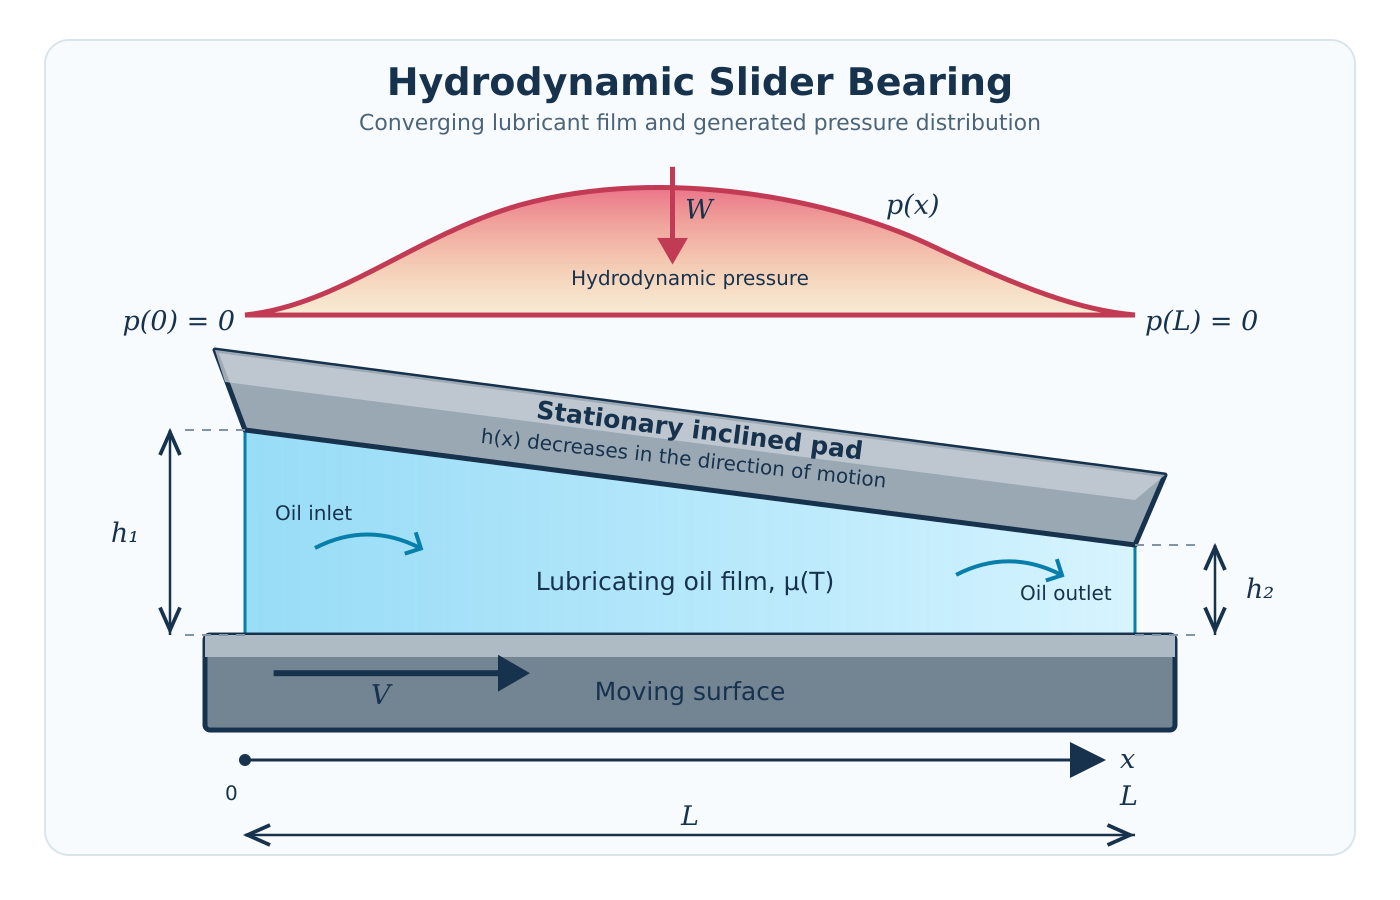

## Problem description

A hydrodynamic slider bearing consists of a stationary inclined pad and a flat moving surface separated by a thin film of lubricating oil. The lower surface moves with velocity $V$, dragging lubricant into the converging gap. The resulting pressure distribution allows the bearing to support a normal mechanical load.

In this project, experimental viscosity data will first be used to determine a temperature-dependent viscosity model. Experimental pressure measurements will then be used to describe the pressure distribution along the bearing. A physically constrained polynomial approximation will provide a smooth pressure curve and an estimate of the maximum pressure. Finally, Newton–Cotes formulas will be used to estimate the total load carried by the bearing and its effective position.

Considering this and the figure, we will determine:

a. The viscosity of the oil at operating temperature. 

b. The polynomial approximation of the pressure distribution. 

c. The maximum pressure and its position. 

d. The bearing's load-carrying capacity. 

Use the following data:

**Note: **$ $b$
$**is the bearing dimension perpendicular to the plane shown in the figure.**

The film thickness varies linearly along the bearing:


$$
 h(x)=h_1+\frac{h_2-h_1}{L}x,
 \qquad 0\leq x\leq L
$$


Pressure is measured relative to ambient pressure. The measurements at the inlet and outlet therefore satisfy


$$
 p(0)=0,
 \qquad
 p(L)=0
$$


Assume the nonlinear viscosity model


$$
 \mu(T)=A\exp\left(\frac{B}{T}\right)
$$


where $A$ and $B$ are unknown parameters.

### Problem 2a. Estimate viscosity of the oil (6 pts)

The experimental measurements are provided in the external workbook *`bearing_viscosity_measurements.xlsx`. *The worksheet *`viscosity_measurements`* contains 25 measurements and the columns *`temperature_C`, `temperature_K`, and `viscosity_Pa_s*`.

Before fitting the model, verify that all required columns exist, that the data contain no missing or non-finite entries, and that all Kelvin temperatures and viscosity measurements are positive. The temperature used in the viscosity model must always be expressed in kelvin.

Estimate the parameters in the nonlinear viscosity model using linear least squares. Plot the datapoints and the fitted model. What is the viscosity of the oil at the operating temperature?

# Solution 2a

#### Data Loading

V = readmatrix("bearing_viscosity_measurements.xlsx", "Sheet", 'viscosity_measurements', 'range', 'B2:C26');

#### Solution

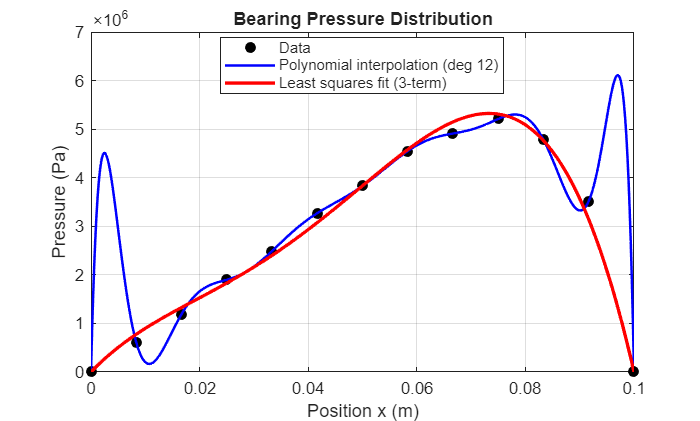

% mu(T) = A * exp(B/T) = ypts
% log(mu(T)) = log(A) * B/T = log(ypts)



Tpts = V(:,1); %temp
ypts = log(V(:,2)); % visc

X = zeros(25, 2);
X(:, 1) = 1;
X(:, 2) = 1./Tpts;

charlies = X\ypts;

const1 = exp(charlies(1, 1))
const2 = charlies(2, 1)

muT = const1 * exp(const2./Tpts) 
ypts = exp(ypts)

relative_error = abs((ypts - muT)./ypts);
max_relative_error = max(relative_error)

% plotting
figure;
plot(ypts, Tpts, muT, Tpts)
hold off;
ylabel('Temperature')
xlabel('Viscosity')
title('True Vector vs. Solved Vector')
grid on;

The Viscosity of the fluid is approximately governed by the equation:


$$\mu(T) = A \cdot e^{\left(\frac{B}{T}\right)} \approx 2.1906 \times 10^{-8} \cdot e^{\left(\frac{4.9738 \times 10^{3}}{T}\right)}
$$


This equation has a maximum relative error between the measured viscosity and the approximated viscosity of 0.0077, or approximately 0.77 percent.

### Problem 2b. The polynomial approximation of the pressure distribution (12 pts)

The worksheet `pressure_measurements` in the same Excel workbook contains 13 measurements and the columns `measurement_id`, `position_m`, and `pressure_Pa`.

First, compute the polynomial **interpolation** to all datapoints. 

Next, use linear least squares fitting to approximate the coefficients in the model

$
  p(s)=s(1-s)\left(c_0+c_1s+c_2s^2\right)
 }.
$, where $
 s=\frac{x}{L},
 \qquad 0\leq s\leq1$.

Note this is a fourth-degree polynomial, but with particular form to ensure the pressure is zero at either endpoint. Be specific about the design matrix and vector.

Plot both models together with the datapoints and comment on either model.

# Solution 2b

#### Data Loading

P = readmatrix("bearing_viscosity_measurements.xlsx","Sheet", 'pressure_measurements');

Here the pressure data is loaded.

#### Solution

x  = P(:,2);  
p  = P(:,3);    
L  = 0.1;
s  = x / L;

%p_interp = polyfit(x, p, length(x)-1);
p_interp = polyfit(s, p, length(s)-1);

I = 2.4403e+04

Here the polynomial interpolation is computed. 

Changed the polynomial interpolation in terms of s and not x so that it is better conditioned.

A = [s - s.^2, s.^2 - s.^3, s.^3 - s.^4];
c = A \ p;

The least squares system is calculated and solved using backslash.

xf = linspace(0, L, 500)';
sf = xf / L;
p_ls  = c(1)*(sf-sf.^2) + c(2)*(sf.^2-sf.^3) + c(3)*(sf.^3-sf.^4);
%p_int = polyval(p_interp, xf);

I = 2.4397e+04

p_int = polyval(p_interp, sf); 

figure
plot(x, p, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Data'); hold on;
plot(xf, p_int, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Polynomial interpolation (deg 12)');
plot(xf, p_ls,  'r-', 'LineWidth', 2,   'DisplayName', 'Least squares fit (3-term)');
xlabel('Position x (m)');
ylabel('Pressure (Pa)');

I = 2.4401e+04

title('Bearing Pressure Distribution');
legend('Location', 'best');
grid on;

Here the data points, the least-squares fit, and the polynomial interpolation is plotted.

### Problem 2c. The maximum pressure and its position (4 pts)

Using your degree 4 polynomial approximation, determine the maximum pressure and the point at which the maximum pressure is attained.

# Solution 2c


$$p'(s) = c_0(1 - 2s) + c_1(2s - 3s^2) + c_2(3s^2 - 4s^3)$$



$$-4c_2\, s^3 + 3(c_2 - c_1)\, s^2 + 2(c_1 - c_0)\, s + c_0 = 0$$



$$s_1 \approx 0.7329, \qquad s_{2,3} \approx 0.1488 \pm 0.2112\,i$$



$$s^* = s_1 \approx 0.7329$$



$$x^* = s^* L \approx 0.0733\ \mathrm{m}, \qquad
p_{\max} = p(s^*) \approx 5.32 \times 10^{6}\ \mathrm{Pa}$$


The maximum pressure point was found analytically by taking the derivative, setting it to 0, and solving it. We have two imaginary roots and one real root, therefore the real root is our maximum. This amounts to approximately 5.32 Mpa.

### Problem 2d. The bearing's load-carrying capacity (8 pts)

The pressure produces a normal force on the pad. The total load carried by the bearing is


$$
  W=b\int_0^L p(x)\,dx
 $$


Again use the degree 4 polynomial approximation for $p(x)$. Determine the total load using the composite midpoint rule, the composite trapezoidal rule, and the composite Simpson's $\frac{1}{3}$ rule. Compare against the analytical value of the integral. For each of the rules, analyse how quickly the errors decrease as the number of function evaluations is increased. Which of the rules do you prefer here?

# Solution 2d

#### Composite Midpoint Rule

f = @(x) c(1)*x*L^-1 - c(1)*x.^2*L^-2 + c(2)*x.^2*L^-2 - c(2)*x.^3*L^-3 + c(3)*x.^3*L^-3 - c(3)*x.^4*L^-4;

ans = 1.1604e+07

a = 0;

ans = -2.2174e+07

b = L;

ans = 5.9279e+07

n = 100;

L = 0.1000

b_width = 0.08;


W = 2.4401e+04


I = b_width*composite_midpoint(f, a, b, n)

Calculating the total load using the composite midpoint rule.

#### Composite Trapezoidal Rule

f = @(x) c(1)*x*L^-1 - c(1)*x.^2*L^-2 + c(2)*x.^2*L^-2 - c(2)*x.^3*L^-3 + c(3)*x.^3*L^-3 - c(3)*x.^4*L^-4;
a = 0;
b = L;
n = 100;

I = b_width*trapezoid(f, a, b, n)

Calculating the total load using the trapezoidal rule.

#### Composite Simpon's 1/3 Rule

f = @(x) c(1)*x*L^-1 - c(1)*x.^2*L^-2 + c(2)*x.^2*L^-2 - c(2)*x.^3*L^-3 + c(3)*x.^3*L^-3 - c(3)*x.^4*L^-4;
a = 0;

T = 6×4 table
     n     Midpoint    Trapezoid     Simpson  
    ___    ________    _________    __________

      4     1202.5      2451.3          15.437
      8     310.75       624.4         0.96483
     16     78.322      156.82        0.060302
     32      19.62      39.251       0.0037689
     64     4.9075      9.8157      0.00023555
    100     2.0103      4.0207      3.9519e-05


b = L;
n = 100;

I = b_width*simpson(f, a, b, n)

Calculating the total load using the composite simpson's 1/3 rule.

#### Analytical Value

Our equation is:


$$p(x) = c_1 x L^{-1} - c_1 x^2 L^{-2} + c_2 x^2 L^{-2} - c_2 x^3 L^{-3} + c_3 x^3 L^{-3} - c_3 x^4 L^{-4}$$


Therefore out integral is:


$$W = b\int_0^L \left( c_1 x L^{-1} - c_1 x^2 L^{-2} + c_2 x^2 L^{-2} - c_2 x^3 L^{-3} + c_3 x^3 L^{-3} - c_3 x^4 L^{-4} \right) dx$$


Integrating we get:


$$W = b\left[ \frac{1}{2}c_1 x^2 L^{-1} - \frac{1}{3}c_1 x^3 L^{-2} + \frac{1}{3}c_2 x^3 L^{-2} - \frac{1}{4}c_2 x^4 L^{-3} + \frac{1}{4}c_3 x^4 L^{-3} - \frac{1}{5}c_3 x^5 L^{-4} \right]_0^L$$


If we substiute in our limits we get:


$$W = b\left[ \frac{1}{2}c_1 L - \frac{1}{3}c_1 L + \frac{1}{3}c_2 L - \frac{1}{4}c_2 L + \frac{1}{4}c_3 L - \frac{1}{5}c_3 L \right]$$


Now we solve by substiuting in our values for c1, c2, c3, and L:

c(1)
c(2)
c(3)
L

W = b_width*(1/2*c(1)*L - 1/3*c(1)*L + 1/3*c(2)*L - 1/4*c(2)*L + 1/4*c(3)*L - 1/5*c(3)*L)

#### Comparison of Methods



ns = [4 8 16 32 64 100];   
E = zeros(length(ns), 3);
for k = 1:length(ns)
    n = ns(k);
    E(k,1) = abs(b_width*composite_midpoint(f, a, b, n) - W);
    E(k,2) = abs(b_width*trapezoid(f, a, b, n)          - W);
    E(k,3) = abs(b_width*simpson(f, a, b, n)            - W);
end

T = table(ns', E(:,1), E(:,2), E(:,3), ...
    'VariableNames', {'n','Midpoint','Trapezoid','Simpson'})

Here we create a table comparing the absolute error of each of the methods.

We can see that the Simpson's 1/3 rule reaches the lowest absolute error at n=100 and reaches a small error very quickly at n=2. Therefore it is the best method for this problem. It is still not exact because our polynomial is higher than order 3.